%[XTrain,~,YTrain] = digitTrain4DArrayData;
%[XValidation,~,YValidation] = digitTest4DArrayData;

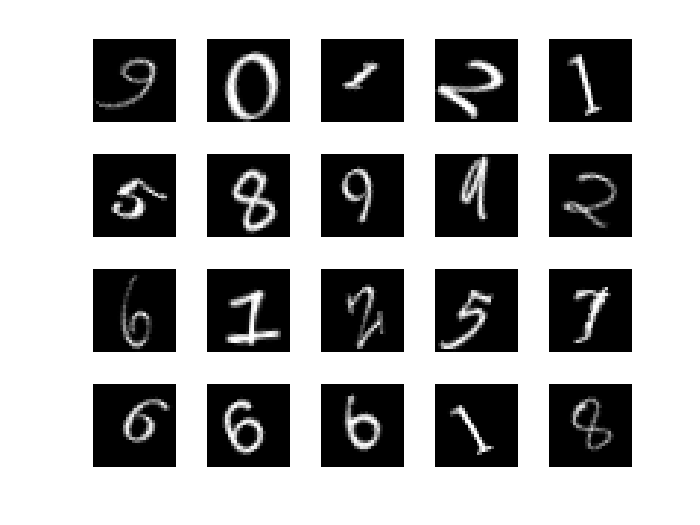

numTrainImages = numel(YTrain);
figure
idx = randperm(numTrainImages,20);
for i = 1:numel(idx)
    subplot(4,5,i)    
    imshow(XTrain(:,:,:,idx(i)))
end

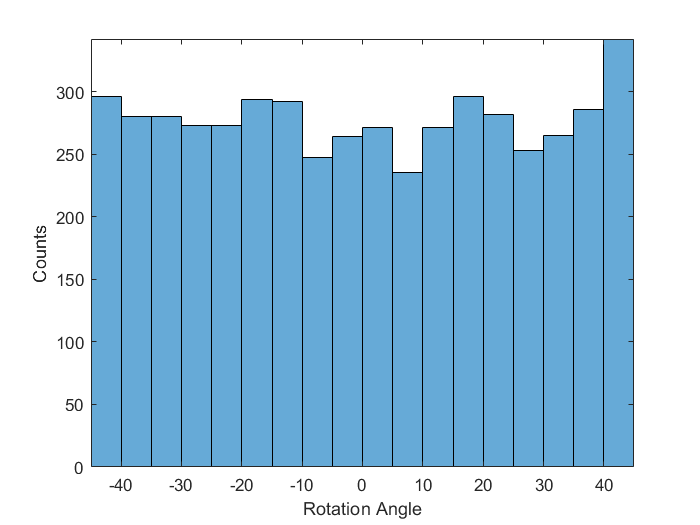

figure
histogram(YTrain)
axis tight
ylabel('Counts')
xlabel('Rotation Angle')


%define the network
layers = [
    imageInputLayer([28 28 1])
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    averagePooling2dLayer(2,'Stride',2)
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    dropoutLayer(0.2)
    fullyConnectedLayer(1)
    regressionLayer];

miniBatchSize  = 128;
validationFrequency = floor(numel(YTrain)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',30, ...
    'InitialLearnRate',1e-3, ...
    'LearnRateSchedule','piecewise', ...
    'LearnRateDropFactor',0.1, ...
    'LearnRateDropPeriod',20, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XValidation,YValidation}, ...
    'ValidationFrequency',validationFrequency, ...
    'Plots','training-progress', ...
    'Verbose',false);

net = trainNetwork(XTrain,YTrain,layers,options);

YPredicted = predict(net,XValidation);
predictionError = YValidation - YPredicted;
%threshold value
thr = 10;
numCorrect = sum(abs(predictionError) < thr);
numValidationImages = numel(YValidation);

accuracy = numCorrect/numValidationImages

accuracy = 0.9706


squares = predictionError.^2;
rmse = sqrt(mean(squares))

rmse = single
4.5180

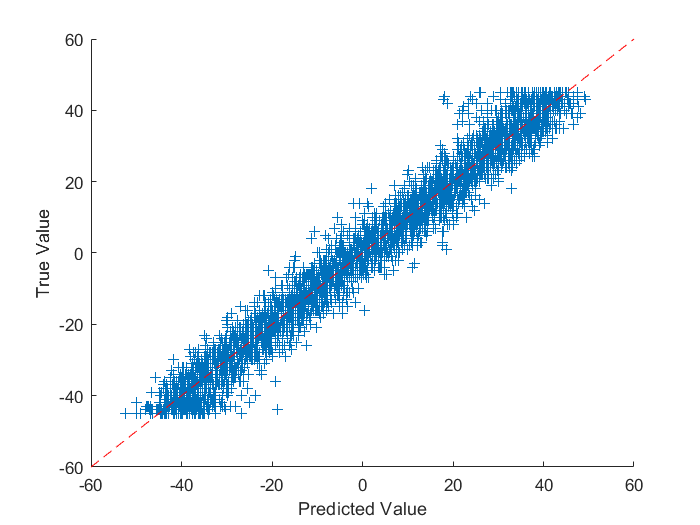


figure
scatter(YPredicted,YValidation,'+')
xlabel("Predicted Value")
ylabel("True Value")

hold on
plot([-60 60], [-60 60],'r--')

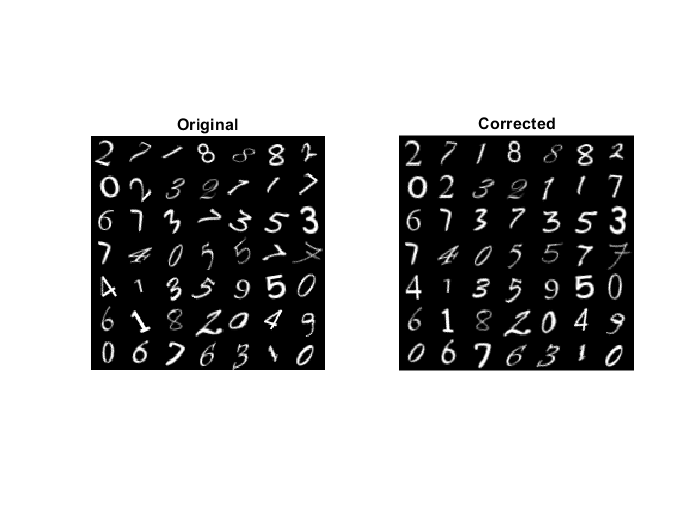

idx = randperm(numValidationImages,49);
for i = 1:numel(idx)
    image = XValidation(:,:,:,idx(i));
    predictedAngle = YPredicted(idx(i));  
    imagesRotated(:,:,:,i) = imrotate(image,predictedAngle,'bicubic','crop');
end

figure
subplot(1,2,1)
montage(XValidation(:,:,:,idx))
title('Original')

subplot(1,2,2)
montage(imagesRotated)
title('Corrected')